clc;
close all;
M=8

M = 8

k=log2(M);
n=3000;
sps = 1

sps = 1

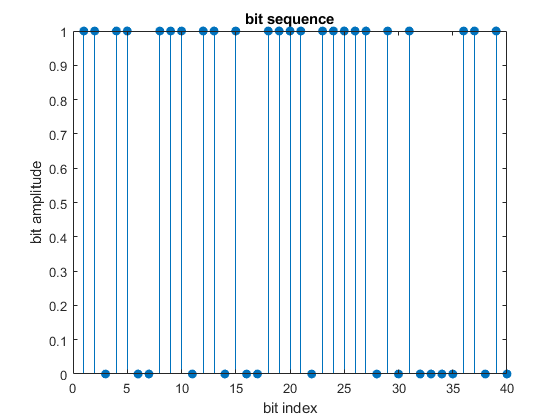

nsamp=1;
rng default;
x = randi([0 1],n,1);
stem(x(1:40),'filled');
title('bit sequence');
xlabel('bit index');
ylabel('bit amplitude');

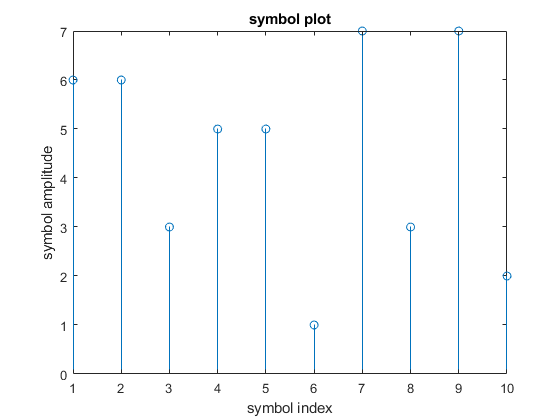

xsym=bi2de(reshape(x,k,length(x)/k).','left-msb');
figure;
stem(xsym(1:10));
title('symbol plot');
xlabel('symbol index');
ylabel('symbol amplitude');

y=y(x,k);

Index in position 1 is invalid. Array indices must be positive integers or logical values.

y=modulate(modem.qammod(M),xsym);
ytx=y;
ebno=10
snr=ebno+10*log(k)-10*log10(nsamp);
yn=awgn(ytx,snr);
yrx=yn;
scatter plot(y);
scatter plot(yrx,30);
